Esercizio 1 - FFT su segnale 1D, analisi e filtraggio

Lettura file audio

path = 'PinkPanther30.wav';
[x, FS] = audioread(path);

Visualizzazione nel tempo e nella frequenza del segnale audio

info = audioinfo(path);
t = 0:seconds(1/FS):seconds(info.Duration);
t = t(1:end-1);
figure(1)
subplot(2,2,1); plot(t,x);
xlabel('time'); ylabel('audio Signal'); title('Diagramma temporale prima');

calcolo la FT di x(n) tramite FFT

X = fft(x);

traccio l'istogramma

[M, N] = size(t);
freq = (0:N/2) * FS/(N);

grafico istogramma

subplot(2,2,2); stem(freq, abs(X(1:N/2 +1)),'b');
xlabel('frequency'); ylabel('Amplitude'); title('Istogramma delle frequenze prima');

Filtraggio in frequenza

H = ones(1, N);
H(freq > 600) = 0;

isolo i suoni bassi

copia la prima metà del vettore H nella seconda, per simmetria

H(N/2 +1 : N) = fliplr(H(1:N/2));
X = X .* (H');
X = X .* 2; %sempre per la simmetria
subplot(2,2,4); stem(freq, abs(X(1:N/2 +1)),'b');
xlabel('frequency'); ylabel('Amplitude'); title('Istogramma delle frequenze dopo');

Ritorno nel dominio del tempo dopo il filtraggio

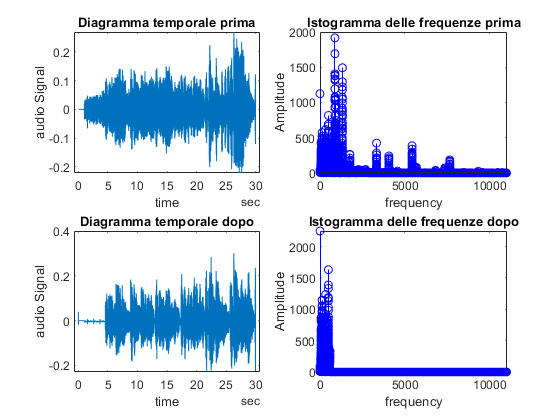

x = real(ifft(X));
subplot(2,2,3); plot(t, x);
xlabel('time'); ylabel('audio Signal'); title('Diagramma temporale dopo');

Riproduzione e salvataggio dell'audio ottenuto

sound(x, FS); % riproduce l'audio alla frequenza corretta
audiowrite('PinkPanther30_bassi.wav', x, FS)